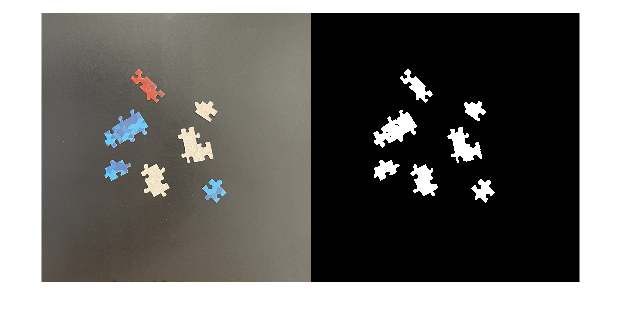

img = imread("Puzzle_01.jpg");
montage({img, BW})

function [BW_out,properties] = filter3PiecesRegions(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 21-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Fill holes in regions.
BW_out = imfill(BW_out, 'holes');

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[19000, 28628]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'MajorAxisLength', 'MinorAxisLength', 'Perimeter'});
end

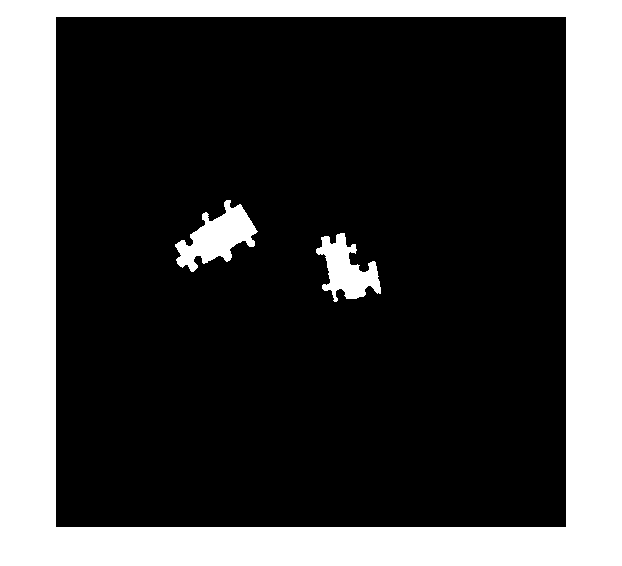

[BW_out, properties] = filter3PiecesRegions(BW);

imshow(BW_out)

properties2 = regionprops("table", BW_out, "BoundingBox")

properties2 = 2×1 table
              BoundingBox           
    ________________________________

    353.5    542.5      246      216
    771.5    640.5      194      206


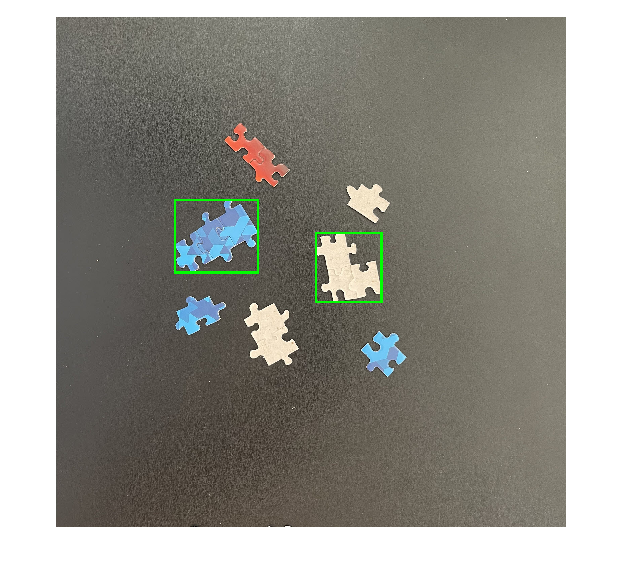

img2 = insertShape(img, "rectangle", properties2.BoundingBox,"color", "green" ,"LineWidth",7);
imshow(img2)

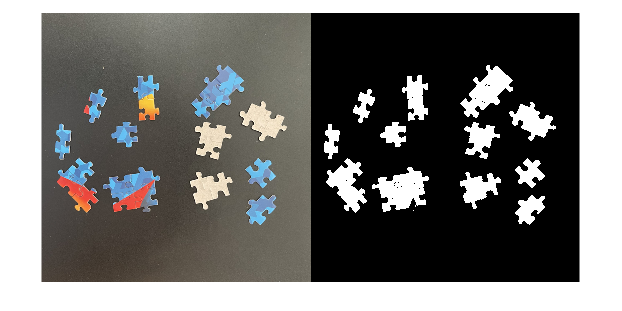

img3 = imread("Puzzle_02.jpg");
montage({img3, BW3})

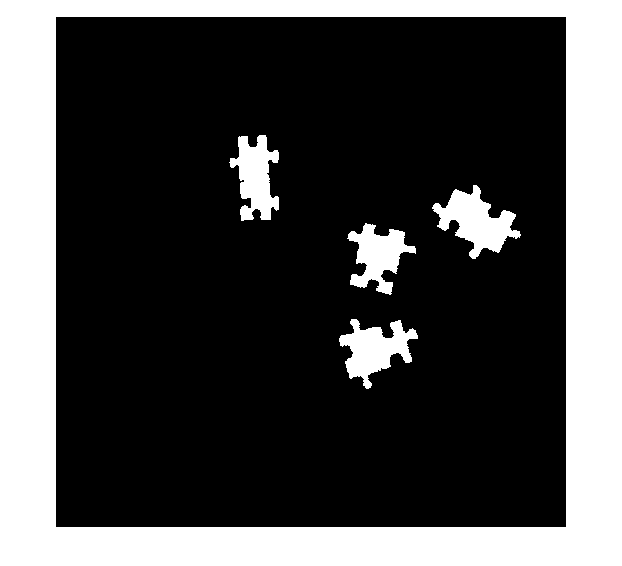

[BW_out3, properties] = filter3PiecesRegions(BW3);

imshow(BW_out3)

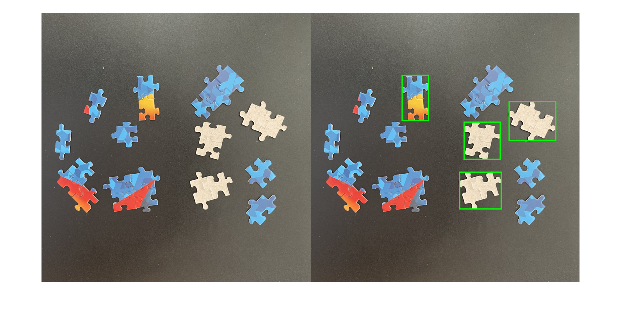

properties3 = regionprops("table", BW_out3, "BoundingBox");
img3_3piece = insertShape(img3, "rectangle", properties3.BoundingBox, "color", "green", "LineWidth", 7);

montage({img3, img3_3piece})